**算法思路：**

    逐步剥离最大绝对值附件的波形；

    并且相邻的波形不能有所重叠，否则放弃该最大值附近的波形。

**边界情况讨论：**

    1. 舍弃首末两端附近的尖峰波形；

         **讨论：**

                有一种方法能够稍微避免首末端附近的尖峰长度不一致的问题，

                就是在SpikesX每行的序列中记录Spikes波形的起始-结束坐标点，而且能简化SpikesX矩阵的元素个数。这样的话，首末情况也能够添加进来。

                但是这样的话，会引入不少问题，比如大部分Spikes波形宽度一致，仅两端不一致。后续进行无监督聚类是就是在不同的特征空间上，比较麻烦。

                但不如此处直接将首末两端潜在的Spikes波形舍弃。相对于整体较长的序列而言，其影响几乎可以忽略不计。

    2. 在初始化空矩阵式使用 int16.empty(nRows, nColumns)能稍微规范化一些；

    3. 迭代剥离过程的终止条件：

        1. 剩余波形的RMS远小于原波形的RMS；

        2. 遍历了所有的最值，及其附近的波形，都不满足不重叠的要求；

**关键性的参数：**

1. C 对原波形取阈值操作；函数输入参数

2. W决定每个波形的半边宽度；函数输入参数

3. alpha， 终止条件，RMS的阈值取值；程序中默认为0.1

程序及其结果如下：

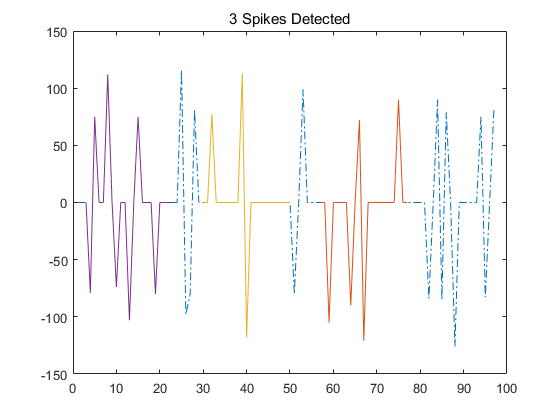

r = unidrnd(100, 1, 100);
[fd, threshold, ffd] = ThreshFiltered(r, 1.2);

[restList, SpikesX, SpikesY] = SpikesDetection(ffd, 10);

figure;
plot(ffd, '-.');hold on;

for i=1:size(SpikesX, 1)
    plot(SpikesX(i, :), ffd(SpikesX(i, :)));hold on;
end
title([num2str(size(SpikesX, 1)), ' Spikes Detected'])